### Datos

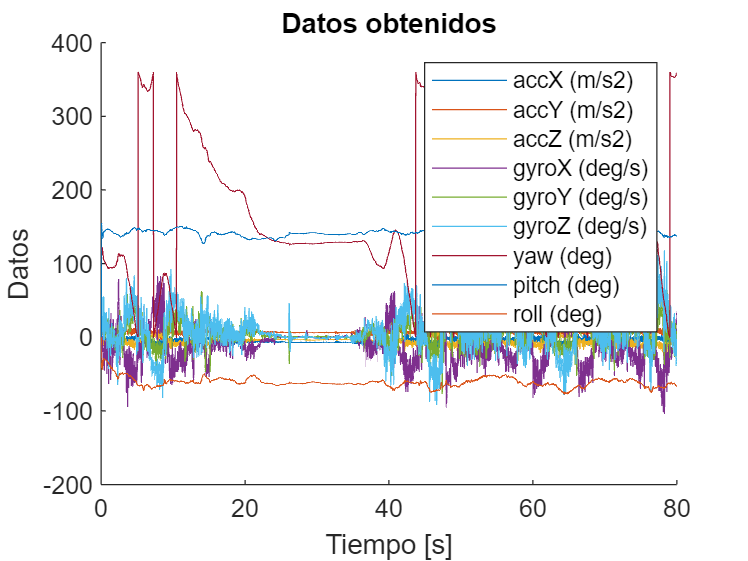

% Leer el archivo JSON como una cadena
jsonString = fileread('Datos_Karts.json');

% Obtener datos de archivo Json
jsonData = jsondecode(jsonString);
nombres = {jsonData.payload.sensors.name}; 
unidades = {jsonData.payload.sensors.units}; 
valores = jsonData.payload.values; 

% frecuencia de muestreo
tiempo = 80;
N = length(valores); 
Fs=N/tiempo;
% Se crea vector de tiempo 
t = linspace(0, tiempo, N); 

% Grafica de todos los valores
figure;
hold on;

for i = 1:length(nombres)
    plot(t, valores(:, i), 'DisplayName', [nombres{i} ' (' unidades{i} ')']); 
end

xlabel('Tiempo [s]'); 
ylabel('Datos');
title('Datos obtenidos');
legend('show');

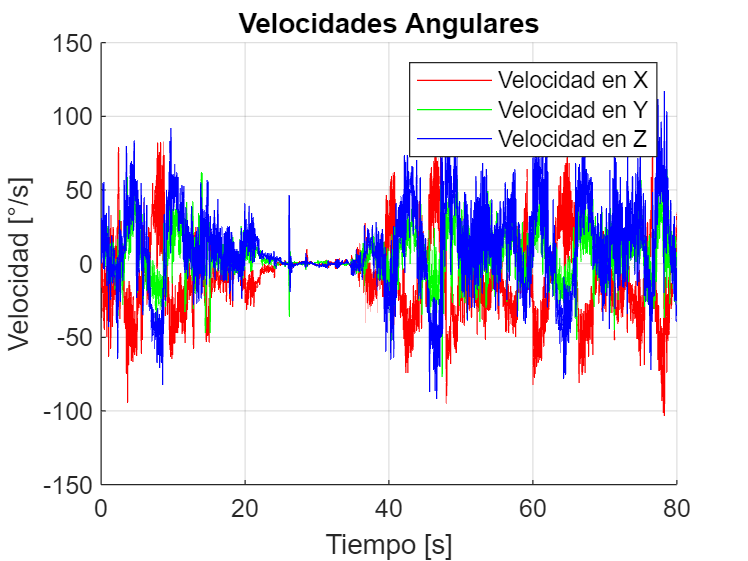


% Velocidades
iwx = 4; 
iwy = 5; 
iwz = 6; 

W_x = valores(:, iwx);
W_y = valores(:, iwy);
W_z = valores(:, iwz);


% Aceleraciones 
iax = 1; 
iay = 2; 
iaz = 3; 

A_x= valores(:, iax);
A_y= valores(:, iay);
A_z= valores(:, iaz);

% Orientaciones
iy = 7; 
ip = 8; 
ir = 9; 

Y= valores(:, iy);
P= valores(:, ip);
R= valores(:, ir);

% Grafica de velocidades
figure;
hold on;

plot(t, W_x, 'r', 'DisplayName', 'Velocidad en X'); 
plot(t, W_y, 'g', 'DisplayName', 'Velocidad en Y');
plot(t, W_z, 'b', 'DisplayName', 'Velocidad en Z'); 

xlabel('Tiempo [s]');
ylabel('Velocidad [°/s]');
title('Velocidades Angulares');
legend('show');
grid on;

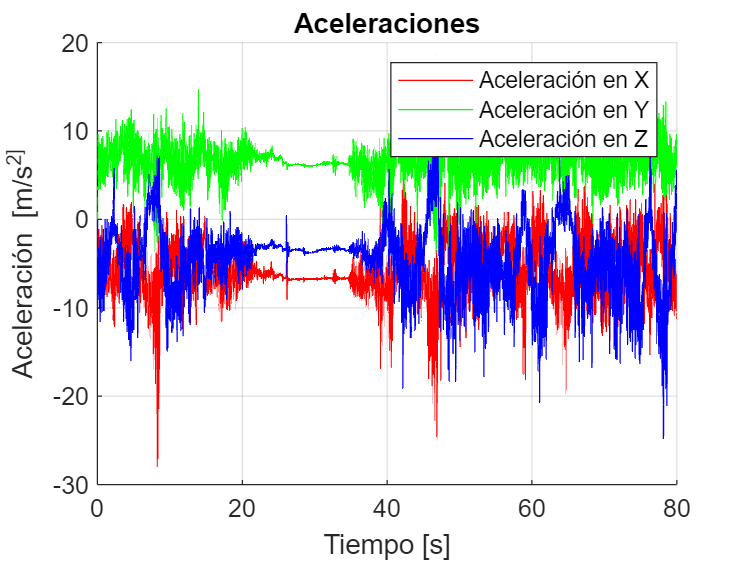

% Grafica de aceleraciones
figure;
hold on;

plot(t, A_x, 'r', 'DisplayName', 'Aceleración en X'); 
plot(t, A_y, 'g', 'DisplayName', 'Aceleración en Y');
plot(t, A_z, 'b', 'DisplayName', 'Aceleración en Z'); 

xlabel('Tiempo [s]');
ylabel('Aceleración [m/s^2]');
title('Aceleraciones');
legend('show');
grid on;

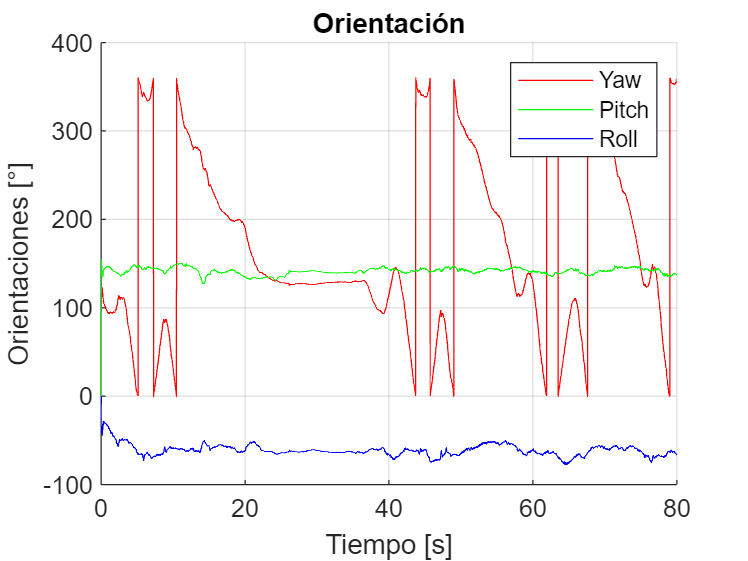

% Grafica de Orientaciones
figure;
hold on;

plot(t, Y, 'r', 'DisplayName', 'Yaw'); 
plot(t, P, 'g', 'DisplayName', 'Pitch');
plot(t, R, 'b', 'DisplayName', 'Roll'); 

xlabel('Tiempo [s]');
ylabel('Orientaciones [°]');
title('Orientación');
legend('show');
grid on;

### Filtrado

#### Transformada rapida de Fourier

fftAx = fft(A_x);  
fftAy = fft(A_y);  
fftAz = fft(A_z);  

fftWx = fft(W_x);  
fftWy = fft(W_y);  
fftWz = fft(W_z);  

fftP = fft(P);  
fftY = fft(Y);  
fftR = fft(R);

#### Filtro Butterworth

FC = 0.55;  
orden = 4;   
[b, a] = butter(order, FC / (fs / 2), 'low');  

Axf = filter(b, a, A_x);
Ayf = filter(b, a, A_y);
Azf = filter(b, a, A_z);

Wxf= filter(b, a, W_x);
Wyf = filter(b, a, W_y);
Wzf = filter(b, a, W_z);

%Transformada rapida de Fourier para señales filtradas
fftAxf = fft(Axf);  
fftAyf = fft(Ayf);  
fftAzf = fft(Azf);  

fftWxf = fft(Wxf);  
fftWyf = fft(Wyf);  
fftWzf = fft(Wzf);  

% Frecuencias 
frequencias = (0:N-1)*(fs/N);
frequencias = frequencias(1:floor(N/2));  

% Magnitudes Normalizadas
%Señal sin filtrar

magAx = abs(fftAx/N); 
magAy = abs(fftAy/N);  
magAz = abs(fftAz/N);  

magWx = abs(fftWx/N);  
magWy = abs(fftWy/N);  
magWz = abs(fftWzf/N);  

%Señal filtrada
magAxF = abs(fftAxf/N); 
magAyF = abs(fftAyf/N);  
magAzF = abs(fftAzf/N);  

magWxF = abs(fftWxf/N);  
magWyF = abs(fftWyf/N);  
magWzF = abs(fftWzf/N);    

% Mitad positiva de FFT
magWx = magWx(1:floor(N/2));
magWy = magWy(1:floor(N/2));
magWz = magWz(1:floor(N/2));

magAx = magAx(1:floor(N/2));
magAy = magAy(1:floor(N/2));
magAz = magAz(1:floor(N/2));

magWxF = magWxF(1:floor(N/2));
magWyF = magWyF(1:floor(N/2));
magWzF = magWzF(1:floor(N/2));

magAxF = magAxF(1:floor(N/2));
magAyF = magAyF(1:floor(N/2));
magAzF = magAzF(1:floor(N/2));

**Graficas de FFT**

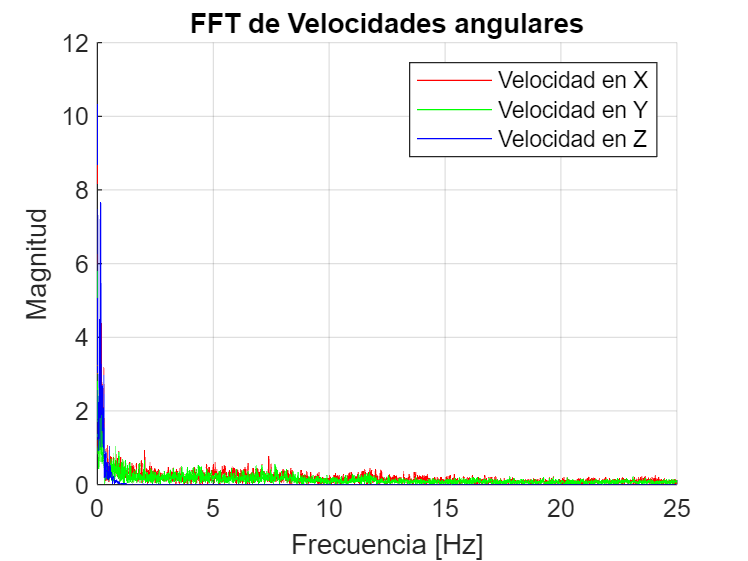


%FFT sin filtrar
%velocidad angular
figure;
hold on;

plot(frequencias, magWx, 'r', 'DisplayName', 'Velocidad en X');
plot(frequencias, magWy, 'g', 'DisplayName', 'Velocidad en Y');
plot(frequencias, magWz, 'b', 'DisplayName', 'Velocidad en Z');

xlabel('Frecuencia [Hz]');
ylabel('Magnitud');
title('FFT de Velocidades angulares');
legend('show');
grid on;

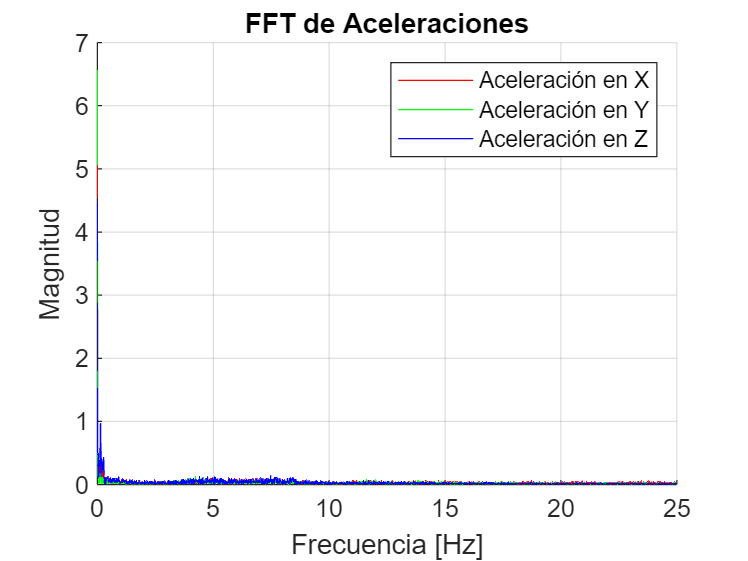


%Aceleración
figure;
hold on;

plot(frequencias, magAx, 'r', 'DisplayName', 'Aceleración en X');
plot(frequencias, magAy, 'g', 'DisplayName', 'Aceleración en Y');
plot(frequencias, magAz, 'b', 'DisplayName', 'Aceleración en Z');

xlabel('Frecuencia [Hz]');
ylabel('Magnitud');
title('FFT de Aceleraciones');
legend('show');
grid on;

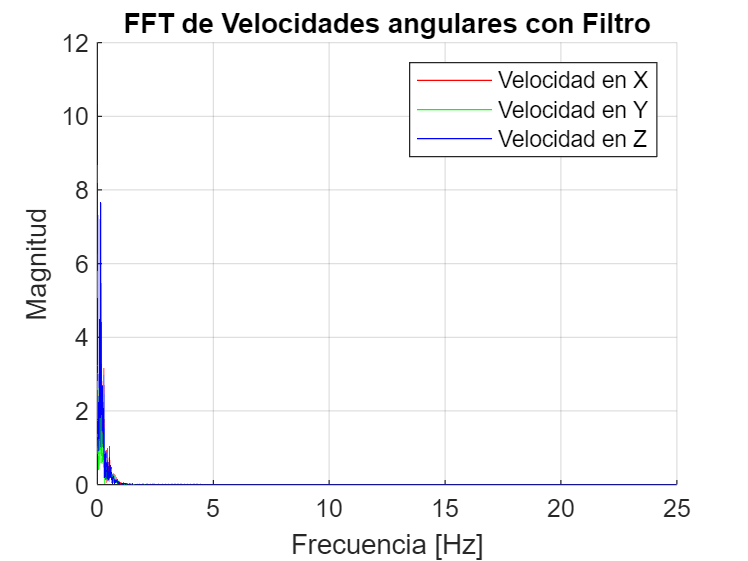




% FFT con filtro

%velocidad angular
figure;
hold on;

plot(frequencias, magWxF, 'r', 'DisplayName', 'Velocidad en X');
plot(frequencias, magWyF, 'g', 'DisplayName', 'Velocidad en Y');
plot(frequencias, magWzF, 'b', 'DisplayName', 'Velocidad en Z');

xlabel('Frecuencia [Hz]');
ylabel('Magnitud');
title('FFT de Velocidades angulares con Filtro');
legend('show');
grid on;

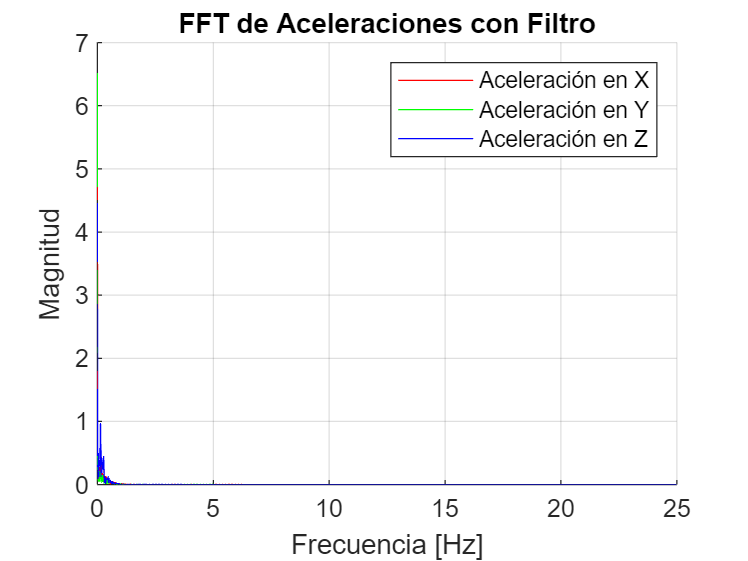


%Aceleración
figure;
hold on;

plot(frequencias, magAxF, 'r', 'DisplayName', 'Aceleración en X');
plot(frequencias, magAyF, 'g', 'DisplayName', 'Aceleración en Y');
plot(frequencias, magAzF, 'b', 'DisplayName', 'Aceleración en Z');

xlabel('Frecuencia [Hz]');
ylabel('Magnitud');
title('FFT de Aceleraciones con Filtro');
legend('show');
grid on;

**Graficas de datos con filtro**

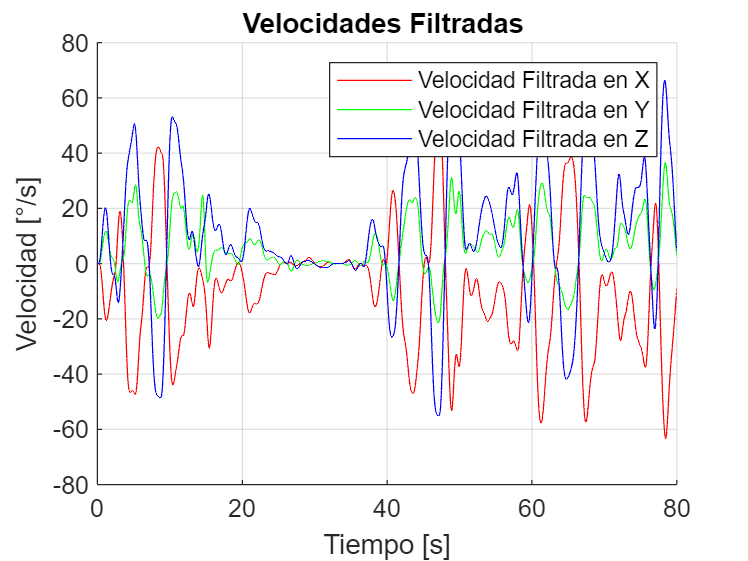

% Velocidades
figure;
hold on;  % 

plot(t, Wxf, 'r', 'DisplayName', 'Velocidad Filtrada en X');
plot(t, Wyf, 'g', 'DisplayName', 'Velocidad Filtrada en Y');
plot(t, Wzf, 'b', 'DisplayName', 'Velocidad Filtrada en Z');

xlabel('Tiempo [s]');
ylabel('Velocidad [°/s]');
title('Velocidades Filtradas ');
legend('show');  
grid on; 

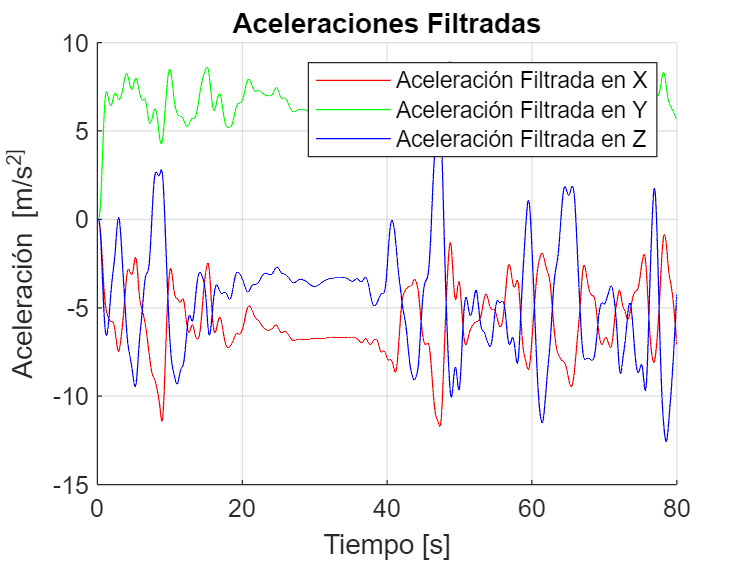

% Aceleraciones
figure;
hold on;  

plot(t, Axf, 'r', 'DisplayName', 'Aceleración Filtrada en X');
plot(t, Ayf, 'g', 'DisplayName', 'Aceleración Filtrada en Y');
plot(t, Azf, 'b', 'DisplayName', 'Aceleración Filtrada en Z');

xlabel('Tiempo [s]');
ylabel('Aceleración [m/s^2]');
title('Aceleraciones Filtradas');
legend('show');  
grid on;  

### Grafica de Posición el tiempo

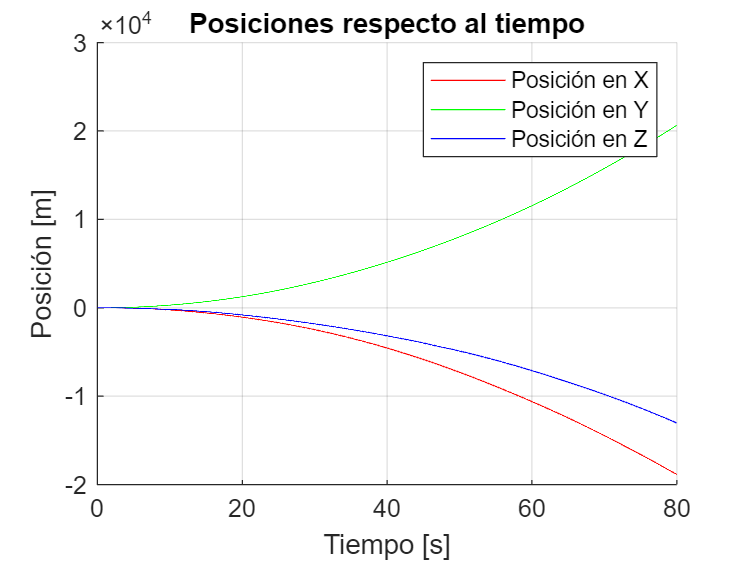


% Cálculo de velocidades integrando aceleraciones
Vxf = cumtrapz(t, Axf);  
Vyf = cumtrapz(t, Ayf);  
Vzf = cumtrapz(t, Azf);  

% Cálculo de posiciones integrando velocidades
X = cumtrapz(t, Vxf);  
Y = cumtrapz(t, Vyf); 
Z = cumtrapz(t, Vzf); 

% Graficas de posiciones con respecto al tiempo
figure;
hold on;
plot(t, X, 'r', 'DisplayName', 'Posición en X'); 
plot(t, Y, 'g', 'DisplayName', 'Posición en Y');
plot(t, Z, 'b', 'DisplayName', 'Posición en Z'); 

xlabel('Tiempo [s]');
ylabel('Posición [m]');
title('Posiciones respecto al tiempo');
legend('show');
grid on;

### Datos sin la gravedad

Ya con los valores de velocidades angulares y aceleraciones filtrados se elimina la influencia que pueda tener la gravedad, obteniendo unicamente los componentes perpenticulares a esta.

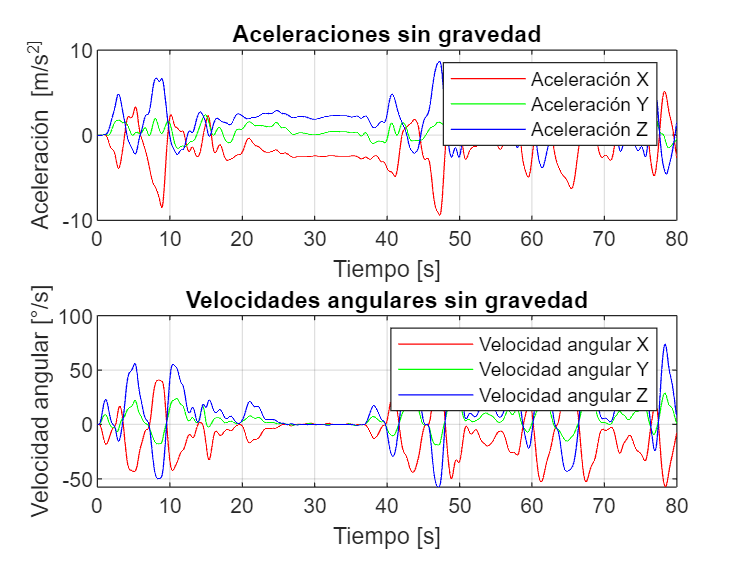

%Se evalua en 40s
t0 = 40 ;
g_vector = [Axf(t0), Ayf(t0), Azf(t0)];
%Vector unitario de la gravedad
g_norm = g_vector / norm(g_vector); 

%Matrices de aceleraciones y velocidades
A = [Axf, Ayf, Azf];  
W = [Wxf, Wyf, Wzf];      

% Se inicalizan para las proyecciones
Ap = zeros(size(A));  % Aceleraciones proyectadas
Wp = zeros(size(W));  % Velocidades angulares proyectadas

% Proyecciones en el plano perpenticular de la gravedad
%Se elimina componente alineado en direccion de la gravedad

% Velocidades
for k = 1:size(W, 1)
    Wp(k, :) = W(k, :) - dot(g_norm, W(k, :)) * g_norm;  
end

%Aceleraciones
for k = 1:size(A, 1)
    Ap(k, :) = A(k, :) - dot(g_norm, A(k, :)) * g_norm;  
end
% Graficas de proyecciones
%Aceleraciones
figure;
subplot(2,1,1);
plot(t, Ap(:,1), 'r'); hold on;
plot(t, Ap(:,2), 'g');
plot(t, Ap(:,3), 'b');
xlabel('Tiempo [s]');
ylabel('Aceleración [m/s^2]');
title('Aceleraciones sin gravedad');
legend('Aceleración X', 'Aceleración Y', 'Aceleración Z');
grid on;
%Velocidades
subplot(2,1,2);
plot(t, Wp(:,1), 'r'); hold on;
plot(t, Wp(:,2), 'g');
plot(t, Wp(:,3), 'b');
xlabel('Tiempo [s]');
ylabel('Velocidad angular [°/s]');
title('Velocidades angulares sin gravedad');
legend('Velocidad angular X', 'Velocidad angular Y', 'Velocidad angular Z');
grid on;

### Trayectoria

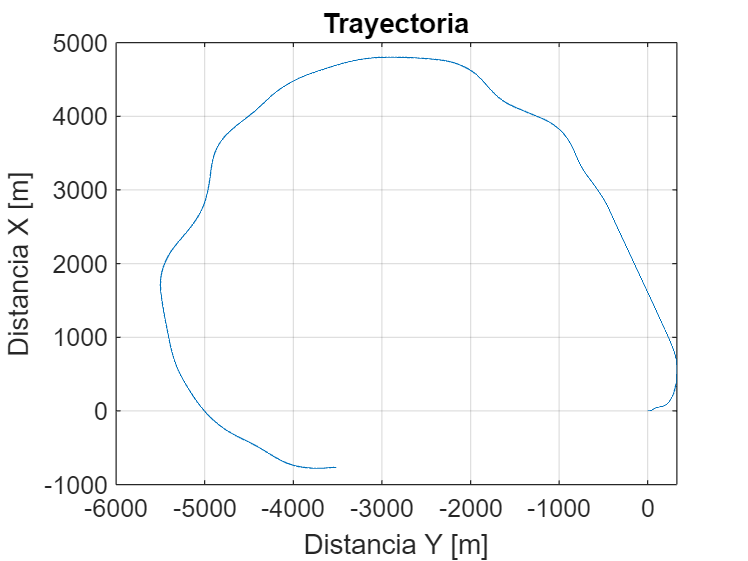

%Se halla el valor promedio por componente de aceleración
Axm = mean(Axf);
Aym = mean(Ayf);
Azm = mean(Azf);
% Vector de aceleracón promedio
Am = [Axm, Aym, Azm]; 

% Se obtiene vector unitario
Am_unitario = Am / norm(Am);

% Se inicializa vector de aceleración tangencial
At = zeros(1, length(Axf)); 

At = zeros(1,length(Axf));
for k = 1:(length(Axf))
   At(k) = dot(Ap(k,:),Am); 
end

%Se encuentra la velocidad integrando la aceleración
V = cumtrapz(t,At)+1; 
%Para la posición de integra la velocidad anterior
S = cumtrapz(t,V); 

%Se halla las posiciones angulares integrando la velocidad angular
thetax = cumtrapz(t,Wp(:,1)) ;
thetay = cumtrapz(t,deg2rad(Wp(:,2)));


ds=diff(S);
xn=zeros(2,length(Axf));
xn(:,1)= [0;0];
 %se actualiza la posición en cada instante sumando el desplazamiento (ds)
 %en las componentes X y Y
for i=1:length(t)-1
    xn(:,i+1)=xn(:,i)+ds(i)*[cos(thetay(i)); sin(thetay(i))];
end   

figure;
plot(xn(1,:),xn(2,:))
title('Trayectoria')
xlabel('Distancia Y [m]');
ylabel('Distancia X [m]');
hold on;
grid on;